#### 5.3.2     `三维曲面`/`网线图`

1`、三维曲面`/`网线可视化的数据准备`

        ` 空间曲面`/`网面表达式有两种：`

`        二元函数：`z=f(x,y) 

`        二元参变函数：`x=f1(s,t)`，`y=f2(s,t)`，`z=f3(s,t)

        ` 绘制三维空间曲面时，需做数据准备：`

`        ▶确定自变量`x,y`的取值范围`x`和取值间隔`

                  x=x1:dx:x2,  y=y1:dy:y2 `或`s=s1:ds:s2,  t=t1:dt:t2

`        ▶构成`x-y`平面上的自变量格点矩阵`

                    [X,Y]=meshgrid(x,y)  `或`   [S,T]=meshgrid(s,t)

                    x/y`及`s/t`都是行或列数组，生成的`X/Y`或`S/T`都是二维矩阵`

`          分别是`x/y `或`s/t`的坐标值（单下标编址）`

`        ▶计算自变量采样格点上的函数值`

                     Z= *f* (X,Y)   `或`  X=F1(S,T)`，`Y=F2(S,T)`，`Z=F3(S,T)

2`、绘制曲面`/`网线图的基本指令`

        surf(Z)            `以`Z`矩阵的列、行下标为` `轴自变量，画曲面图`

        surf(X,Y,Z)                 `最常用的曲面图调用格式，默认`C=Z

        surf(X,Y,Z,C)              `画由`C`指定用色的曲面图`

        surf(X,Y,Z,C,PN,PV)   `带属性名`/`属性值的最完整调用格式`

        Sh= surf( _ )             `返回各种调用格式的句柄`

===========================================================================

        mesh(Z)            `以`Z`矩阵的列、行下标为` `轴自变量，画网线图`

        mesh(X,Y,Z)                   `最常用的网线图调用格式，默认`C=Z

        mesh(X,Y,Z,C)                `画由`C`指定用色的网线图。`

        mesh(X,Y,Z,C,PN,PV) `带属性名`/`属性值的最完整调用格式`

        Mh= surf( _ )                 `返回各种调用格式的句柄`

#### `〖说明〗` 

        `▶ `X`、`Y`是（`x,y`）平面上呈矩形分布的自变量网格点数据数组`

            X`、`Y`、`Z`的数组规模相同，三者给出曲面或网面的全部数据的坐标值`

        `▶ `C`是指定各点用色的矩阵，用户可自行设计，空缺时默认`C=Z

`    ▶ 常用的属性`PN`和名属性值`PV`见表`5.3-1

#### `【例`5.3-2`】用曲面图表现函数`    `。`

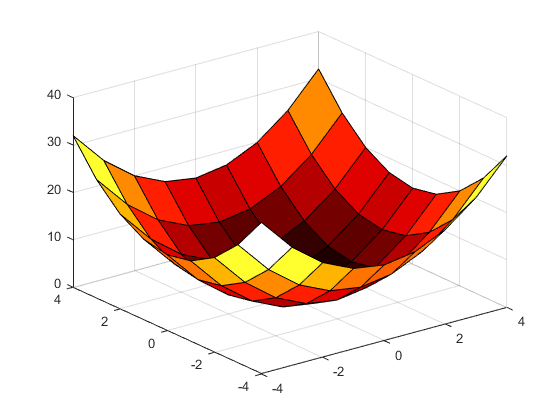

clf
x=-4:4;y=x;         
[X,Y]=meshgrid(x,y);
Z=X.^2+Y.^2;        
surf(X,Y,Z);        %【曲面图】
colormap(hot)       

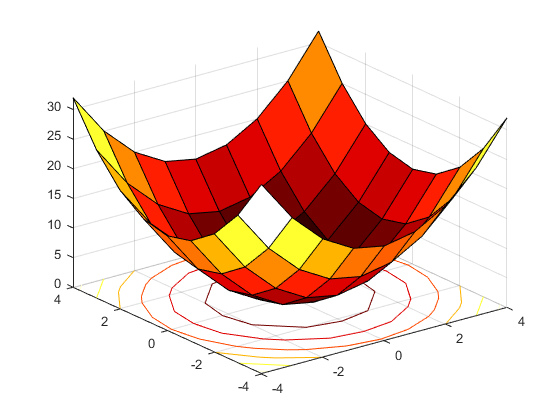

 
surfc(X,Y,Z)       %带等高线的曲面图

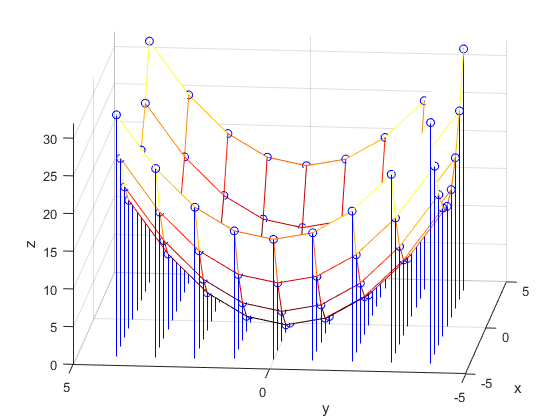

mesh(X,Y,Z)        %网线图
 
hold on
stem3(X,Y,Z,'bo') %stem3(X,Y,Z)三维杆图
hold off
xlabel('x'),ylabel('y'),zlabel('z')
axis([-5,5,-5,5,0,inf]) 
view([-84,21])        

#### 5.3.3   `曲面`**/**`网线图的精细修饰`

**1**、     `视角控制`view

        view([az,el])        `通过方位角（`az o`）、俯视角（`el o`）设置视点`

        view([vx,vy,vz])   `通过直角坐标`vx/vy/vz`设置视点`

        [az,el]=view            `获取当前的方位角和俯视角`

        View(2)                    `设置默认的二维视点`az=0o, el=90o

        View(3)                    `设置默认的三维视点`az=-37.5o, el=30o

#### `〖说明〗`

       `▶ 不使用`view`指令时，默认三维视点`az=-37.5o, el=30o

       `▶ 用`view(2)`设置以习惯的平面直角坐标表现，即二维视点`

       `▶ 可交互式调节视点（【旋转】），调好后由获取满意的视角值`

####          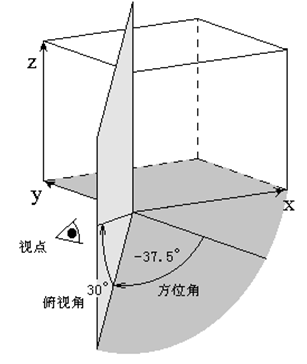

#### `        图`` 5.3-3`  `视点设置参数示意`

#### **2、**  `色调控制`**colormap**

        colormap(CM)          `设置当前图形窗的着色色图为`CM

        colormap(Ax,CM)   `为坐标系专门设置`CM`色调数组`

        colormap                 `给出当前色图，其值在`[0, 1]`之间`

  ` 一个图形窗有多个轴系，可用`colormap(Ax,_)`设置每个轴系的色调`

     CM`取表`5.3-2`所示的预定义内建色调矩阵名称时，可指定的内建`

`    色调矩阵规模为（`M*3`），`M`越大颜色过渡越柔和。`

        CM`也可用户自建，列数必须为`3`，每一行是一个`RGB`三元组取值`[0,1]

     MATLAB`定义了常用的色图矩阵，见表`5.3-2

`                表`5.3-2   MATLAB`预定义的内建色调色组`

####  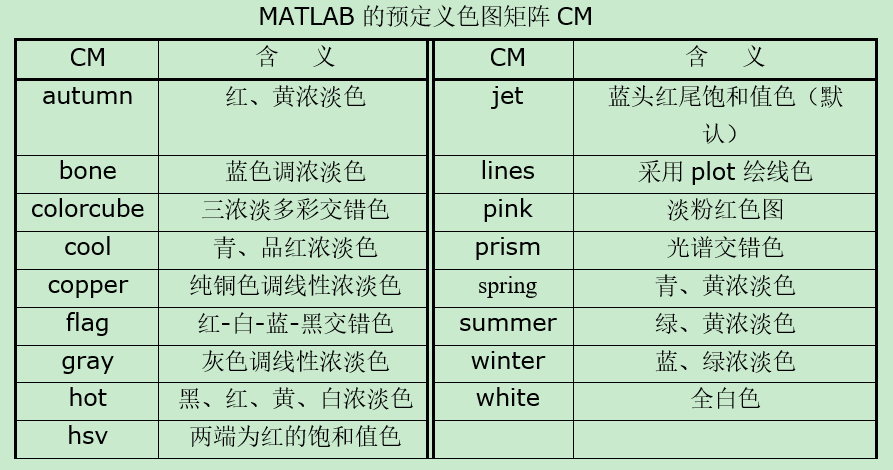

#### ** 3、**`着色模式命令`**shading**

        shading options       `图形对象着色的浓淡处理`

#### `〖说明〗`  

       `▶` mesh`、`surf`、`pcolor`、`fill`、`fill3`等`

`      所创图形非数据点的着色由`shading`指令决定`

       `▶` options`可取三种方式`

            flat`：整条线段或曲面的整个贴片都着一种颜色`

            faceted`：在`flat`用色基础上，贴片四周勾画黑色网线，立体感强（默认）`

            interp`：线段或贴片上各点的颜色经插值获得，用色细腻但耗时`

       `▶` shading`是设置面对象的`EdgeColor`和`FaceColor`属性的高层命令`

#### `【例`5.3-3`】三种浓淡处理方式比较。（图`5.3-4`）`

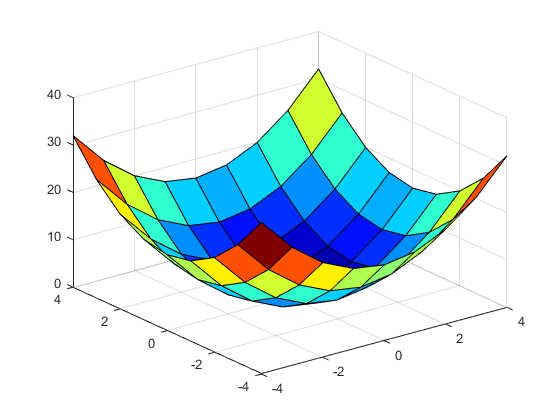

clf                     
x=-4:4;y=x;
[X,Y]=meshgrid(x,y);
Z=X.^2+Y.^2;
surf(X,Y,Z)
colormap(jet)

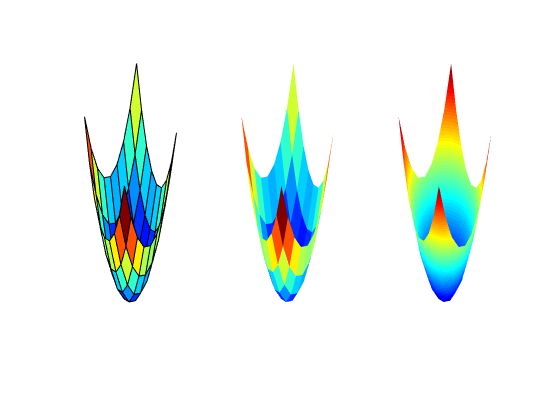

subplot(1,3,1),surf(Z),axis off
subplot(1,3,2),surf(Z),axis off,shading flat
subplot(1,3,3),surf(Z),axis off,shading interp
set(gcf,'Color','w')   % set(gcf,'color','default')可恢复默认底色

#### 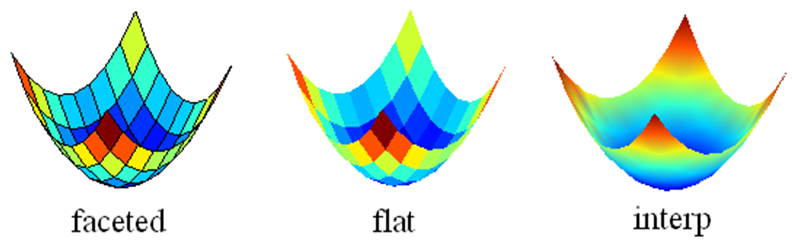

#### `            图 ``5.3-4`  `三种浓淡处理方式比较`

#### **4、** `透明度控制`** alpha**

**       alpha(v)**     `对面、块、像三种图形对象的透明度加以控制`

#### `〖说明〗`

####        `▶` mesh`、`surf`、`slice`等高层指令都适用`

####        `▶` v=0-1, 1`不透明，`0`完全透明`

#### `【例`5.3-4`】表面图的透明控制。`

    peaks`是一种用于演示的函数，为方便测试立体绘图而设置。`

`  曲面包括三个局部极大点和三个局部极小点`

          Z= peaks         `返回`49*49`的`peaks`函数矩阵`

          Z=peaks(n)     `返回`n*n`的`peaks`函数矩阵`

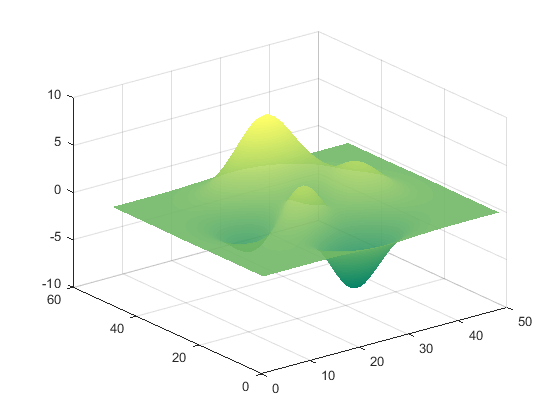

clf
surf(peaks)         % 
shading interp
alpha(0.5)
colormap(summer)  
 
alpha(0.9)         %改变alpha值观察

#### `图` 5.3-8   `peaks图形`

#### **5、** `灯光设置`**light**

        light                          `无穷远白光、通过点`[1,0,1]`射向坐标原点`

        light('color',option1,'style',option2,'position',option3) 

`                     坐标光源设置`

        camlight                  `白色点光源从相机右上方射向坐标框质心`

        camlight options    `根据`option`设置光源位置`

#### `〖说明〗`

`    ▶` `指令使用前采用强度各处相等的漫射光，`

`      执行指令后所有与光有关的属性（如背景光、边缘光）被激活`

`    ▶`  option1`可采用`RGB`三元组或相应的色彩字符，默认白光`[1,1,1]

            option2 `有两个取值，`'infinite' `（无穷远），`'local'`（近光）`

            option3 `采用直角坐标三元组`[x,y,z]`设置`

`            对无穷远光，光线穿过该点射向坐标系原点`

`            对近光该点`[x,y,z]`为光源所在点位置`

`            默认设置：白光、无穷远、穿过`[1,0,1]`射向坐标原点`

`    ▶`   `相机光源`

            options`可取三个值`

                  'headlight' `在相机位置创建光源`

                 'right' `在相机右上方创建光源（默认）`

                 'left' `在相机左上方创建光源`

`      相机位置可从坐标轴系的属性获知，默认时定位于绘图坐标框的质心`

`      默认时相机光源从`options`设定的位置以“点光源`local`”射向绘图坐标框的质心`

#### **6、 **`光线入射命令`**lighting**

        lighting  options     `设置光线入射模式`

#### `〖说明〗`

#### `    ▶ `options`的三种取值：`

                flat`（默认）：与`faceted`配合使用，入射光均匀`

                gouraud`（高氏）：先计算定点法线，再对网格面各点法线线性差值`

                none`：使所有光源关闭`

`    ▶ 只有`light`执行后该指令才起作用`

#### **7、**`光反射命令`material

        material options           `使用预定义反射模式`

#### `〖说明〗`

   `▶ ` options`的四种取值：`

            shiny`：（默认）有高反射光，颜色取决于光源`

            dull`（漫反射份额大）：无高光反射，漫反射多，颜色取决于光源`

            metal`：高反射光大，背景光和漫反射光低，`

`            颜色由光源和图形表面颜色共同决定`

            default`：返回默认设置`

` ▶ 只有`light`执行后该指令才起作用`

#### `【例`5.3-5`】灯光、照明、材质指令所表现的图形。`

       sphere                            `生成`20*20`面组成的球面`

       sphere(n)                       `生成`n*n`面组成的球面`

       [X,Y,Z]= sphere(n)          `生成坐标值，用于`surf`和`mesh`指令`

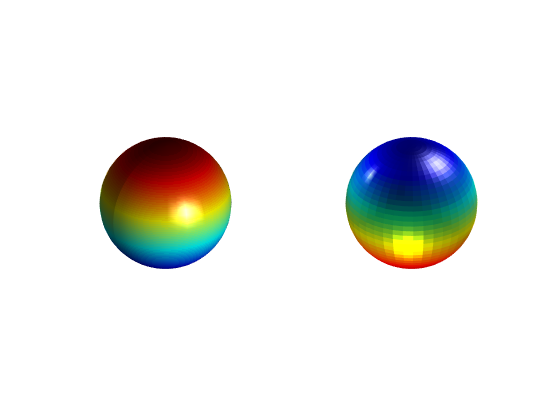

clf;
[X,Y,Z]=sphere(40);
colormap(jet)                              %<3>
subplot(1,2,1),surf(X,Y,Z)               %默认色矩阵Z
axis equal off,shading interp            %<4>
light ('position',[0 -10 1.5],'style','infinite')  %<5>
lighting  gouraud                        %<6>
material shiny                          %<7>
subplot(1,2,2),surf(X,Y,Z,-Z)            %色矩阵-Z
axis equal off,shading flat              %<8>
light;lighting flat                         %<9>
light('position',[-1,-1,-2],'color','y')  %<10>
light('position',[-1,0.5,1],'style','local','color','w')

set(gcf,'Color','w')      

#### `〖说明〗`

    `▶ ` `每个子图可设置多个光源：左图`1`个右图`3`个`

`  ▶ 每个图形窗只能有一个色图`colormap

`  ▶ 每个子图的浓淡处理模式、照明模式、材质等只能定义一次`

#### 5.3.4              `曲面绘制技巧`

1`、`  `图形的透视`

        hidden off       `透视被叠压的图形`

        hidden on        `消隐被叠压的图形`

`〖说明〗`

   ` ▶ `hidden`指令对`surf`指令绘制的表面图不产生任何影响`

   ` ▶ `alpha`指令可对透明度进行更细致的控制`

#### `【例`5.3-a`】透视演示（图`5.3-7`）。`

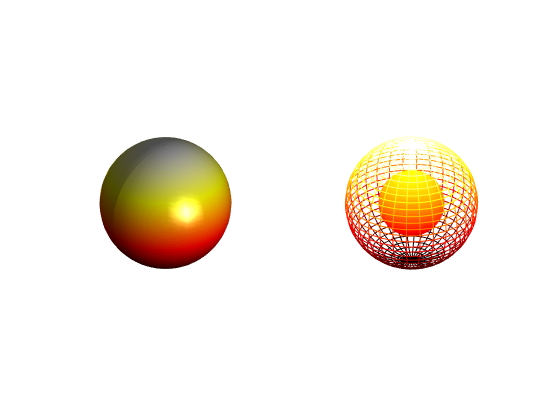

[X0,Y0,Z0]=sphere(30);        
X=2*X0;Y=2*Y0;Z=2*Z0;      
surf(X0,Y0,Z0);            % hidden off不影响
shading interp             
hold on,mesh(X,Y,Z),colormap(hot)    
hold off  
hidden off              % 产生透视
axis equal,axis off    

#### `图``5.3-7`  `剔透玲珑球`

#### `【例`5.3-8`】`

#### `（`1`）球面上铺贴图像`

% close all；
clear
load trees                     %   <3>
TR=flipud(X);                   %  <4>
[X1,Y1,Z1]=sphere(30);           % 
figure
Hs1=surf(X1,Y1,Z1,TR,...      %             <7>
 'CDataMapping','direct',...  %     <8>
 'FaceColor','texturemap',... %          <9>
 'EdgeColor','none');      %                <10>
colormap(map)                   %        <11>
axis equal off                % 
view(-179,22)                   %                <13>

#### `（``2``）透视`

hold on                      %                <14>
X2=1.7*X1;Y2=1.7*Y1;Z2=1.7*Z1; %
mesh(X2,Y2,Z2,Z2+100)         % Z      <16>
hidden off                   % 
hold off                     %                   <18>
set(gcf,'Color','w')          % 

#### `（``3``）旋转内邱`

Nr=30;                    % 
da=360/Nr;                 % 
Ngf=Nr*3;                  % 
GF(Ngf)=struct('cdata',[],'colormap',[]); %     <23>
E=eye(3);                  % 
kk=0;
for k=3:-1:1               % 
 for ii=1:Nr            % 
    rotate(Hs1,E(k,:),da)  %        <28>
    pause(0.1)          %          <29>
    kk=kk+1;
    GF(kk)=getframe(gcf);  %             <31>
  end
end

#### `（``4``）抓的重播功能取图形`

disp('按任意键，播放影片动画！')

按任意键，播放影片动画！


pause
close all                  %          <34>
fig=figure;                %          <35>
movie(fig,GF,1,10)           % <36> 2.非数NaN雕镂图形  利用非数nan对图形镂空

#### `【`5.3-7`】演示：如何利用“非数”`NaN`，对图形进行镂空处理。`

surfc(peaks(30))
P=peaks(30);           
P(18:20,9:15)=NaN;     %【镂空】
surfc(P);              % 带等高线的曲面图
colormap(hot)
light('position',[50,-10,5])
material([0.9,0.9,0.6,15,0.4])
grid off,box on  


#### ` 图``5.3-8`  `镂方孔的曲面`

#### **3.**    `裁切`

#### `将部分图形数据强设为零可对图形进行裁切`

#### `【例`5.3-8`】表现切面（图`5.3-9`）。`

 
clf,x=[-8:0.1:8];
y=x;
[X,Y]=meshgrid(x,y);
ZZ=X.^2-Y.^2;                         %【】
ii=find(abs(X)>6|abs(Y)>6);
%find(A)返回A中所有非零元素的索引值
ZZ(ii)=zeros(size(ii));      
surf(X,Y,ZZ),shading interp;colormap(copper)%【】
light('position',[0,-15,1]);lighting phong
material([0.8,0.8,0.5,10,0.5])   
 

#### `图``5.3-9``  经裁切处理后的图形`

#### 5.4            `高维数据可视化`

5.4.1           `二维半图指令`pcolor, contour, contourf

`【例`5.4-1`】“二维半”指令`pcolor, contour, contourf`的应用。（图`5.4-1`）`

clf;clear;[X,Y,Z]=peaks(40);    
n=6;                        
subplot(1,2,1),
pcolor(X,Y,Z)             
shading interp
zmax=max(max(Z));zmin=min(min(Z));
caxis([zmin,zmax])        
colorbar               
hold on
C=contour(X,Y,Z,n,'k:');  
clabel(C)                
hold off
subplot(1,2,2)
[C,h]=contourf(X,Y,Z,n,'k:');      
clabel(C,h)                 
colormap(cool)              
set(gcf,'Color','w')            
 

#### `图` 5.4-1   `“二维半”指令的演示`

####  5.4.2           `四维表现`

`人对自然界的理解和思维是多维的。人的感官不仅善于接受一维、二维、三维的几何信息，而且对几何物体的运动，对颜色、声音、气味、触感等反应灵敏。从这意义上讲，`MATLAB`色彩控制、动画等指令为四维或更高维表现提供了手段。`

#### `1、准四维表现`

#### `【例`5.4-2`】用颜色表现` `函数的其他特征（如梯度、曲率等）。`

 
clf
x=3*pi*(-1:1/15:1);y=x;[X,Y]=meshgrid(x,y);
R=sqrt(X.^2+Y.^2)+eps;Z=sin(R)./R;
[dzdx,dzdy]=gradient(Z);
dzdr=sqrt(dzdx.^2+dzdy.^2);        %<4>
dz2=del2(Z);                      %<5>
subplot(1,2,1),surf(X,Y,Z,abs(dzdr))  
shading faceted;
colorbar('SouthOutside')          
brighten(0.6);                 
colormap hsv
title('No. 1     surf(X,Y,Z,abs(dzdr))')
subplot(1,2,2);surf(X,Y,Z,abs(dz2))   
shading faceted  
colorbar('NorthOutside')          
title('No. 2     surf(X,Y,Z,abs(dz2))')  
 

#### `图`5.4-2  `色彩分别表现函数的径向导数和曲率特征`

#### **2** 、`切片图`

    [X,Y,Z]=meshgrid(x,y,z) `由采样向量产生三维自变量“格点”数组`

    slice(X,Y,Z,V,sx,sy,sz)      `三元函数切片图`

#### `【例`5.4-3`】图形表现` `。（图`5.4-3`）` 

clf
[x,y,z] = meshgrid(-2:.2:2,-2:.25:2,-2:.16:2);
v =x.*exp(-x.^2-y.^2-z.^2);
xs = [-0.7,0.7]; ys = 0; zs =0;      
slice(x,y,z,v,xs,ys,zs)              
colorbar
shading interp
colormap hsv
xlabel('x'),ylabel('y'),zlabel('z')
title('The color-to-v(x,y,z) mapping')
view([-22,39])
alpha(0.3)  
 

#### `图``5.4-3`  `切片图`

#### 5.4.3  `动态图形`

 `在`MATLAB`的“上层”图形指令中的彗星轨线指令、色图变幻指令、影片动画指令，能很方便地使图形及色彩产生动态变化效果。`

 `由于在`Notebook `和硬拷贝下，这种动态变化效果都无法表现，因此本节所有例题都不提供图形，而只给出有关指令。当读者在`MATLAB`指令窗中运作这些指令后，便可在图形窗中看到相应的动态图形。`

**1.**  `彗星状轨``迹图`

     comet(x,y,p)          `二维彗星轨线`

     comet3(x,y,z,p)      `三维彗星轨线`

`【例` 5.4-4`】简单二维彗星示例。（请读者自己在指令窗中运行以下指令。）`

shg;n=2;t=n*pi*(0:0.000005:1);x=sin(t);y=cos(t);
plot(x,y,'g');axis square
hold on  
comet(x,y,0.0001)
hold off  


**2.** `色图的变幻`

    spinmap                 

    spinmap(t)             

    spinmap(inf)          

    spinmap(t,inc)       

`【例` 5.4-5`】指令`spinmap`的应用。（图`5.4-4`）`

ezsurf('x*y','circ');shading flat;view([-18,28]) 
C=summer;                      
CC=[C;flipud( C )];            
colormap(CC)
spinmap(30,4)                       
 

####  `图`5.4-4  `用于色图变幻演示的图形`

#### **3.**  `影片动画`

        M(i)=getframe             

        movie(M,k)   

`【例`5.4-6`】三维图形的影片动画。（因印刷关系，无法表现本例。请读者自己在指令窗中运行以下指令。）`

clf;shg,x=3*pi*(-1:0.05:1);y=x;[X,Y]=meshgrid(x,y);
R=sqrt(X.^2+Y.^2)+eps; Z=sin(R)./R;
h=surf(X,Y,Z);colormap(jet);axis off
n=12;mmm=moviein(n);      
for i=1:n
   rotate(h,[0 0 1],25);     
   mmm(:,i)=getframe;        
end
movie(mmm,5,10)  


#### **4.**      `实时动画`

#### `【例` 5.5-a`】制作红色小球沿一条带封闭路径的下旋螺线运动的实时动画。`

#### `（`**1**`）``创建函数文件`**anim_zzy1.m**

#### `（`**2**`）``在窗口运行指令`

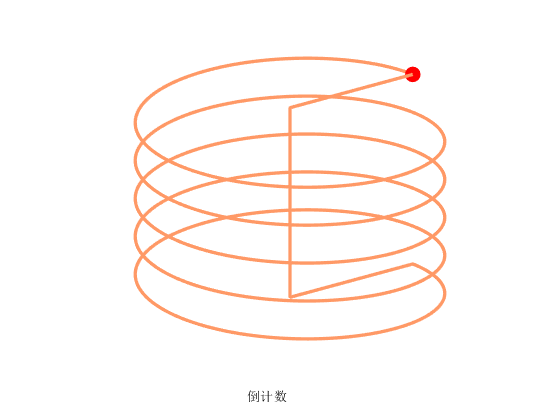

f=anim_zzy1(2,450);

#### `（`**3**`）``显示拍摄照片`

endimage(f.cdata),axis off  

未定义函数或变量 'endimage'。

#### `图5.4-5`  `红球沿下旋螺线运动的瞬间照片`

function f=anim_zzy1(K,ki)
% anim_zzy1.m       演示红色小球沿一条封闭螺线运动的实时动画
% 仅演示实时动画的调用格式为                        anim_zzy1(K)           
% 既演示实时动画又拍摄照片的调用格式为     f=anim_zzy1(K,ki)         
% K                 红球运动的循环数（不小于1）
% ki                指定拍摄照片的瞬间，取 1 到 1034 间的任意整数。
% f                           存储拍摄的照片数据，可用image(f.cdata)观察照片。
 
% 产生封闭的运动轨迹
t1=(0:1000)/1000*10*pi;x1=cos(t1);y1=sin(t1);z1=-t1;
t2=(0:10)/10;x2=x1(end)*(1-t2);y2=y1(end)*(1-t2);z2=z1(end)*ones(size(x2));
t3=t2;z3=(1-t3)*z1(end);x3=zeros(size(z3));y3=x3;
t4=t2;x4=t4;y4=zeros(size(x4));z4=y4;
x=[x1 x2 x3 x4];
n=length(x);
if nargin<2                                                   
    ki=fix(n/2);
end
y=[y1 y2 y3 y4];z=[z1 z2 z3 z4];
shg
plot3(x,y,z,'Color',[1,0.6,0.4],'LineWidth',2.5)      % 绘制运动轨迹
axis off
%定义活动对象的颜色、点型、大小和擦除方式
h=line('xdata',x(1),'ydata',y(1),'zdata',z(1),'Color',[1 0 0],'Marker', '.', 'MarkerSize',40,'EraseMode','xor');
KK=K*n;
text(-1,-0.85,-36,'倒计数')               
KK=KK-1;
htext=text(-1,-1,-40,int2str(KK));
% 使小球运动
i=2;j=1;
while 1                                                        
set(h,'xdata',x(i),'ydata',y(i),'zdata',z(i));         
   drawnow;                                                          %       <23>
   pause(0.0005)                                                        %                 <24>
   i=i+1;
   KK=KK-1;
   set(htext,'string',int2str(KK))                         %  <27>
   if nargin==2 && nargout==1 % 
       if(i==ki&&j==1);f=getframe(gcf);end             %       <29>
   end
   if i>n 
      i=1;j=j+1;
      if j>K;break;end
   end
end 
end
